syms s

lhs = s*(s+5)*(s+6)*(s^2+2*s+2)

$$lhs = s\,\left(s+5\right)\,\left(s+6\right)\,\left(s^{2}+2\,s+2\right)$$

% Compute simplified symbolic expression
simplifiedExpr = expand(lhs)

$$simplifiedExpr = s^{5}+13\,s^{4}+54\,s^{3}+82\,s^{2}+60\,s$$

var = vpa(lhs)

$$var = s\,\left(s+5.0\right)\,\left(s+6.0\right)\,\left(s^{2}+2.0\,s+2.0\right)$$

rhs = (s+3)*diff(s*(s+5)*(s+6)*(s^2+2*s+2),s)

$$rhs = \left(s+3\right)\,\left(\left(s+5\right)\,\left(s+6\right)\,\left(s^{2}+2\,s+2\right)+s\,\left(s+5\right)\,\left(s^{2}+2\,s+2\right)+s\,\left(s+6\right)\,\left(s^{2}+2\,s+2\right)+s\,\left(2\,s+2\right)\,\left(s+5\right)\,\left(s+6\right)\right)$$

a = double(solve(lhs-rhs))

a =   -0.6560 - 0.4677i
  -0.6560 + 0.4677i
  -3.3311 - 1.2040i
  -3.3311 + 1.2040i
  -5.5257 + 0.0000i


syms w

exp = 1-(s+3)/(s*(s+5)*(s+6)*(s^2+2*s+2))

$$exp = 1-\frac{s+3}{s\,\left(s+5\right)\,\left(s+6\right)\,\left(s^{2}+2\,s+2\right)}$$

exp2 = subs(exp,s,1j*w)

$$exp2 = 1+\frac{\left(3+w\,\mathrm{i}\right)\,\mathrm{i}}{w\,\left(5+w\,\mathrm{i}\right)\,\left(6+w\,\mathrm{i}\right)\,\left(-w^{2}+2\,w\,\mathrm{i}+2\right)}$$

b = double(solve(exp2))

b =    0.0000 - 0.0476i
   1.0254 + 1.0259i
  -1.0254 + 1.0259i
   0.0000 + 4.9769i
   0.0000 + 6.0188i


system = tf(-[1,3],[1,13,54,82,60,0])

system =
 
                 -s - 3
  -------------------------------------
  s^5 + 13 s^4 + 54 s^3 + 82 s^2 + 60 s
 
Continuous-time transfer function.
Model Properties


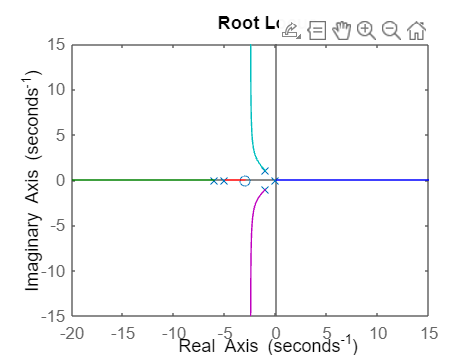

rlocus(system)

system = tf(-[1],[1,3,3,1])

system =
 
           -1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.
Model Properties


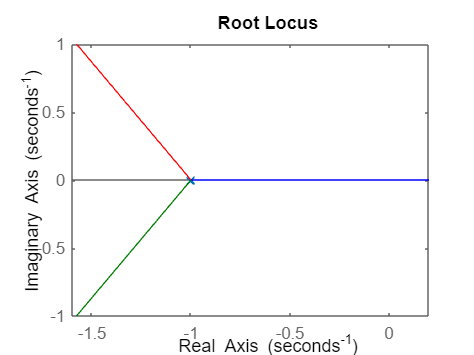

rlocus(system)

system = tf([1],[1,5,10,10,5,1])

system =
 
                     1
  ---------------------------------------
  s^5 + 5 s^4 + 10 s^3 + 10 s^2 + 5 s + 1
 
Continuous-time transfer function.
Model Properties


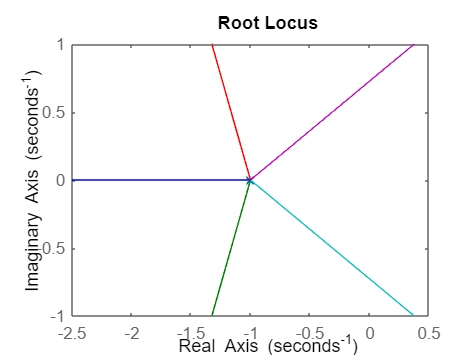

rlocus(system)

system = tf(-[1],[1,5,10,10,5,1])

system =
 
                    -1
  ---------------------------------------
  s^5 + 5 s^4 + 10 s^3 + 10 s^2 + 5 s + 1
 
Continuous-time transfer function.
Model Properties


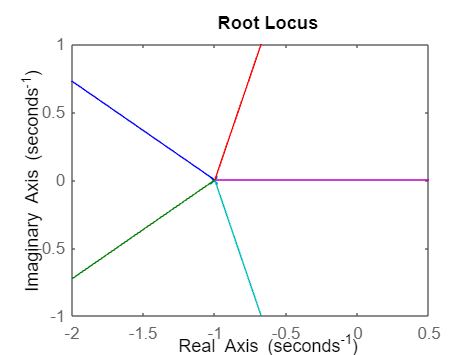

rlocus(system)

sys = tf([10],[1,5,0])

sys =
 
     10
  ---------
  s^2 + 5 s
 
Continuous-time transfer function.
Model Properties


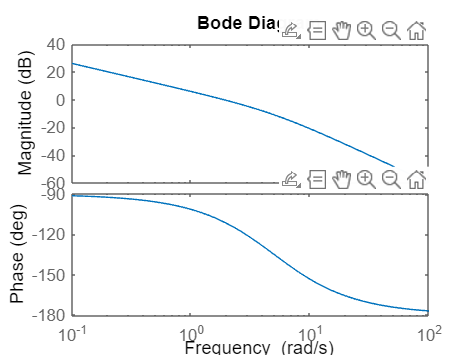

bode(sys)

syms w
a = w^2*(1+w^2)*(1+0.04*w^2)-1;
b = double(solve(a))

b =    0.7793 + 0.0000i
   0.0000 + 1.2842i
   0.0000 + 4.9958i
  -0.7793 + 0.0000i
   0.0000 - 1.2842i
   0.0000 - 4.9958i
